# Yonehara-san wind estimation

Following the PNAS paper outlining a wind estimation method by fitting sine curves to the flight direction and ground speeds, a new method was worked on that instead fit this data to a circle (changing the flight direction from degrees to radians). Yonehara-san mentioned he had greater success with this method than the paper method. To do so, a number of custom functions were written and are displayed in this file.

if ismac()
    fileloc = "/Volumes/GoogleDrive/My Drive/PhD/Data/2016Shearwater/AxyTrek/";
else
    fileloc = "F:/UTokyoDrive/PhD/Data/2016Shearwater/AxyTrek/";
end
files = dir2(strcat(fileloc,"**/*.txt"));
%files = files(3:end);
% extract file names
filesNs = string(split([files.name],'.txt'));
filesNs = filesNs(contains(filesNs,"2016"));
% get file names and dates
tags = strings(length(filesNs),1);
for b = 1:length(filesNs)
    file = char(filesNs(b));
    tags(b) = file(1:strfind(file,'2016')-1);
end
clear file i
% select only unique tag names and find the index of last occurrence
[tags,te] = unique(tags,'last');

dat = cell(length(tags),5);
for tg = 1:length(tags)
    tagfiles = files(startsWith(filesNs,tags(tg))).name;
    fileID = fopen(strcat(fileloc,tags(tg),'/',tagfiles));
    GPSDat = textscan(fileID, '%{dd/MM/yyyy HH:mm:ss}D %f %f %f %f %f %f %f %s','Delimiter','\t','HeaderLines',1);
    fclose(fileID);
    dat{tg,3} = GPSDat{1};
    dat{tg,4} = GPSDat{2};
    dat{tg,5} = GPSDat{3};
end

[time, lat, lon] = gettimelatlon(dat, 1);
[x,y,zone] = deg2utm(lat,lon); % convert from dec degs to UTM
DistTrav = sqrt(diff(x).^2+diff(y).^2); % calculate distance between GPS points
tdiff = diff(time); % time difference between GPS points
spd = DistTrav./seconds(tdiff); % speed travelled, m^-2
dir = atan2(diff(y),diff(x));
[flight,fs,fe] = flightmask(spd,4,5);
[ss,se] = getsection(1,300,60,fs,fe);

A plot of a flight section

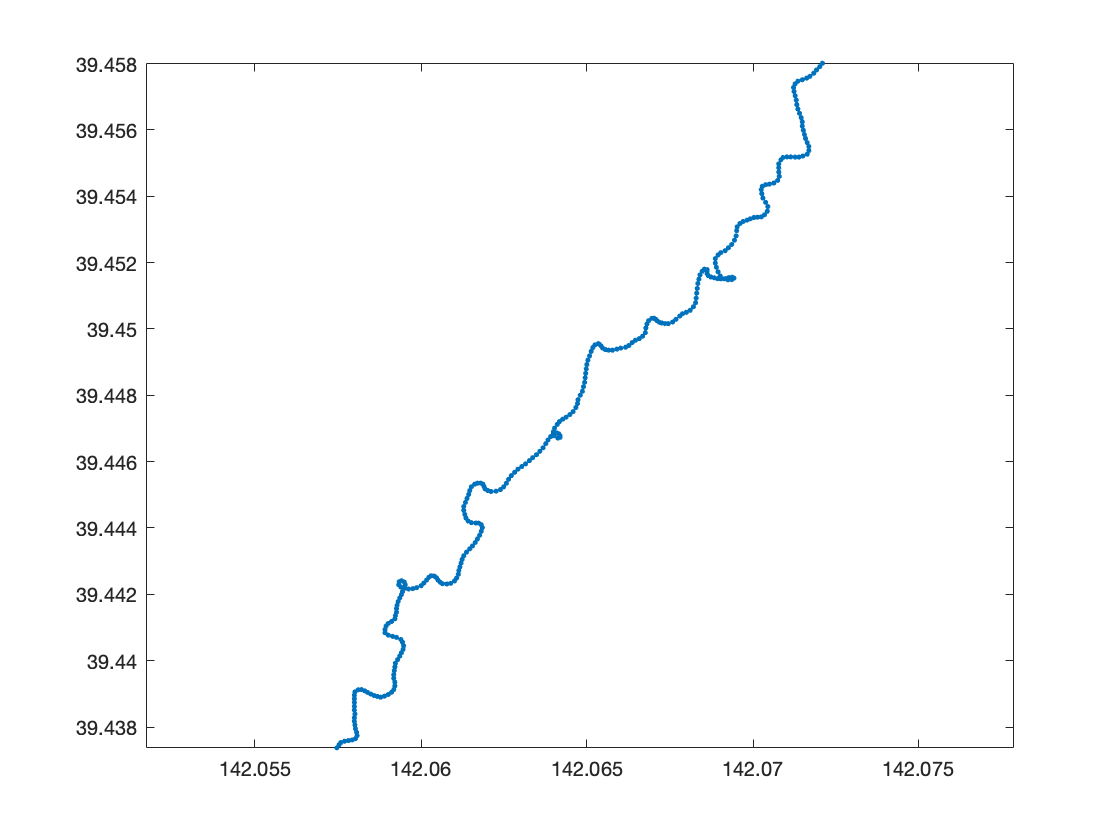

% get variables
t = 468; % section number
vg = spd(ss(t):se(t)); % ground speed
gd = dir(ss(t):se(t)); % track direction
lat1 = lat(ss(t):se(t)); % latitude
lon1 = lon(ss(t):se(t)); % longitude
% plot track
plot(lon1,lat1,'.')
axis equal

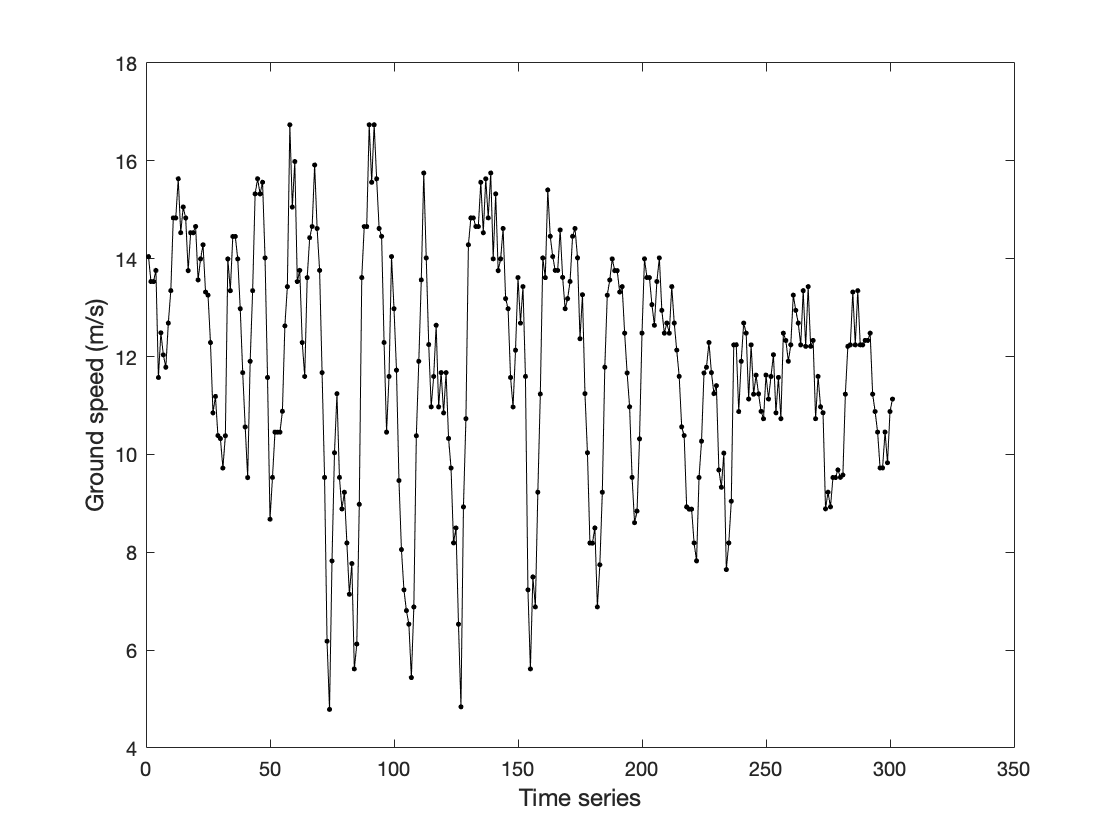

% plot speed time series
plot(vg,'.-k');
xlabel('Time series','FontSize',12);
ylabel('Ground speed (m/s)','FontSize',12);

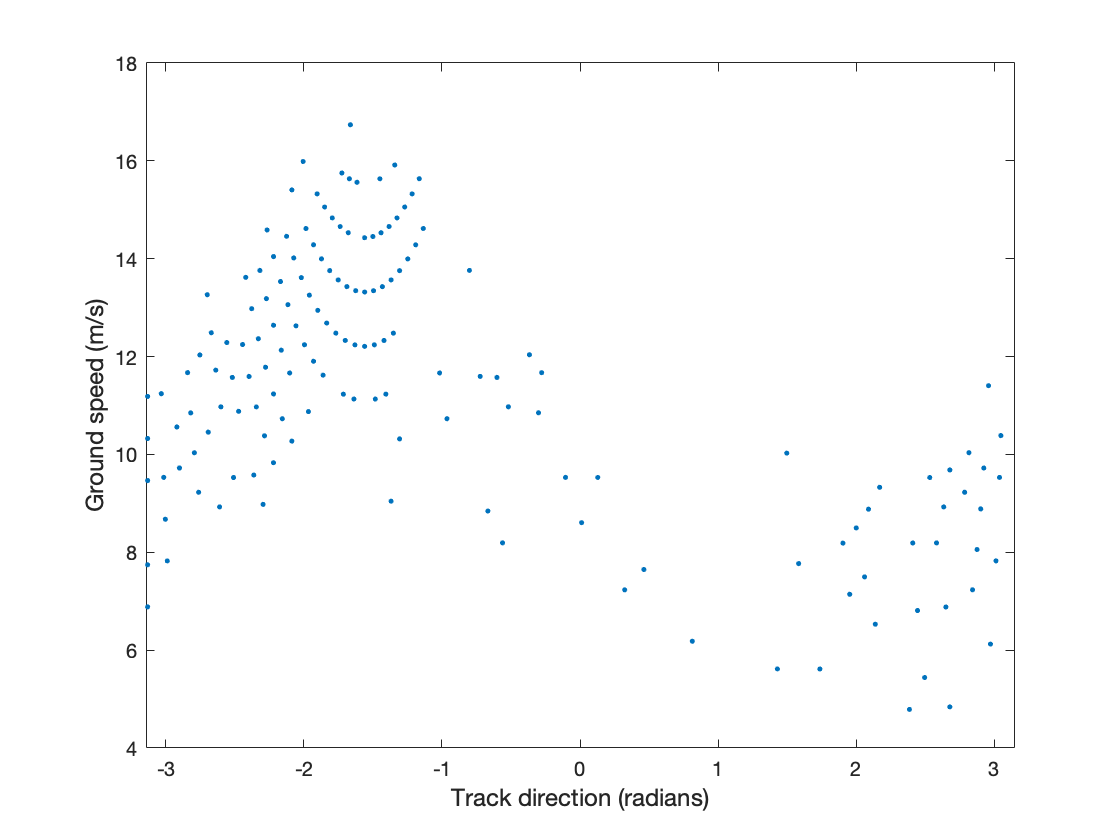


% plot track direction and ground speed on Cartesian coordinate
plot(gd,vg,'.')
xlim([-pi pi]);
xlabel('Track direction (radians)','FontSize',12);
ylabel('Ground speed (m/s)','FontSize',12);

This plot shows the sine curve method used in the original PNAS paper.

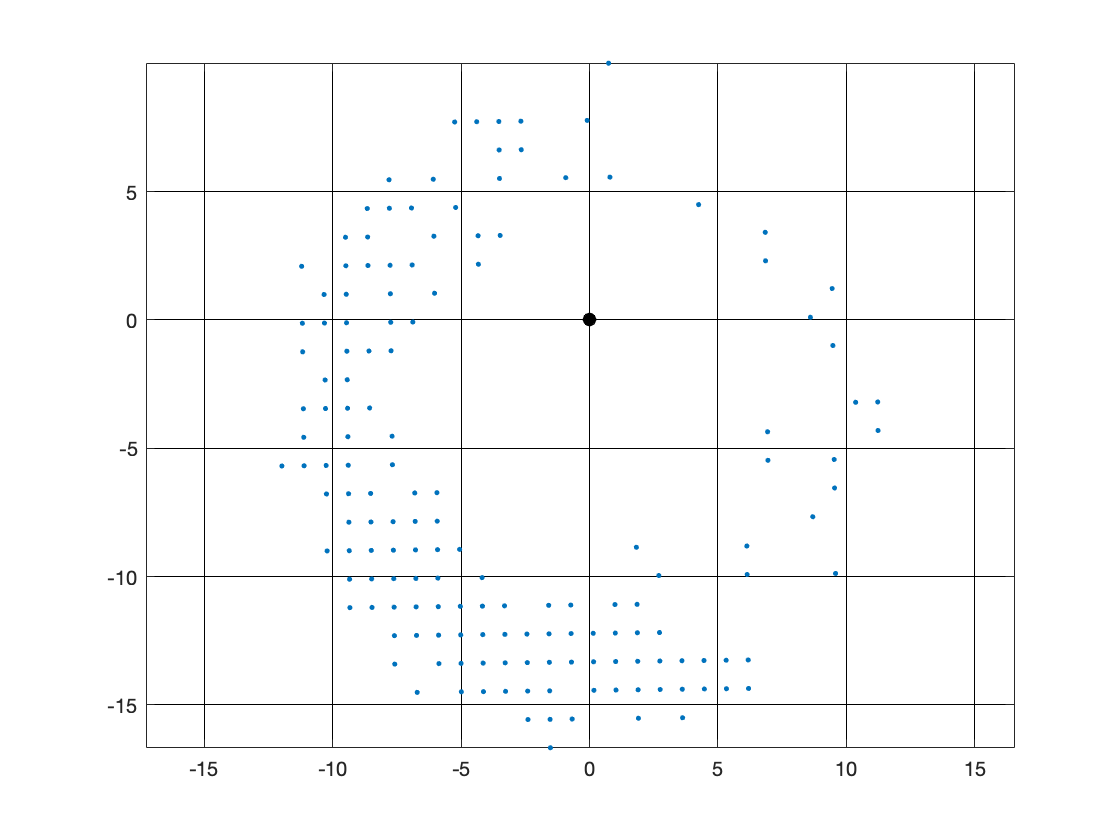


% plot track direction and ground speed on polar coordinate
gx = vg .* cos(gd);
gy = vg .* sin(gd);
plot(gx,gy,'.')
hold on
plot(0,0,'ok','MarkerFaceColor','k')
grid on
ax1 = gca;
ax1.GridColor = [0 0 0];
ax1.GridAlpha = 1;
hold off
axis equal

The center of the circle above plotted with the blue points is offset from the origin. This offset is used to detect the wind vector.

x = -pi:0.01:pi; % heading
x = reshape(x,[],1);

[c,resnorm]=wind2dveclsq(vg,gd,[3 0 9]);
cvec = c;
if cvec(1)<0
    cvec(1) = -cvec(1);
    cvec(2) = cvec(2) -pi;
end
cvec

cvec =     3.3472   -1.5567   10.1991


% get the sum of the squared residuals
eavec = sqrt((gx-cvec(1)*cos(cvec(2))).^2 + (gy-cvec(1)*sin(cvec(2))).^2); % estimated air speed
resnormvec = sum((eavec - cvec(3)).^2) % set residuals as the deviance from the estimated air speed

resnormvec = 567.2262

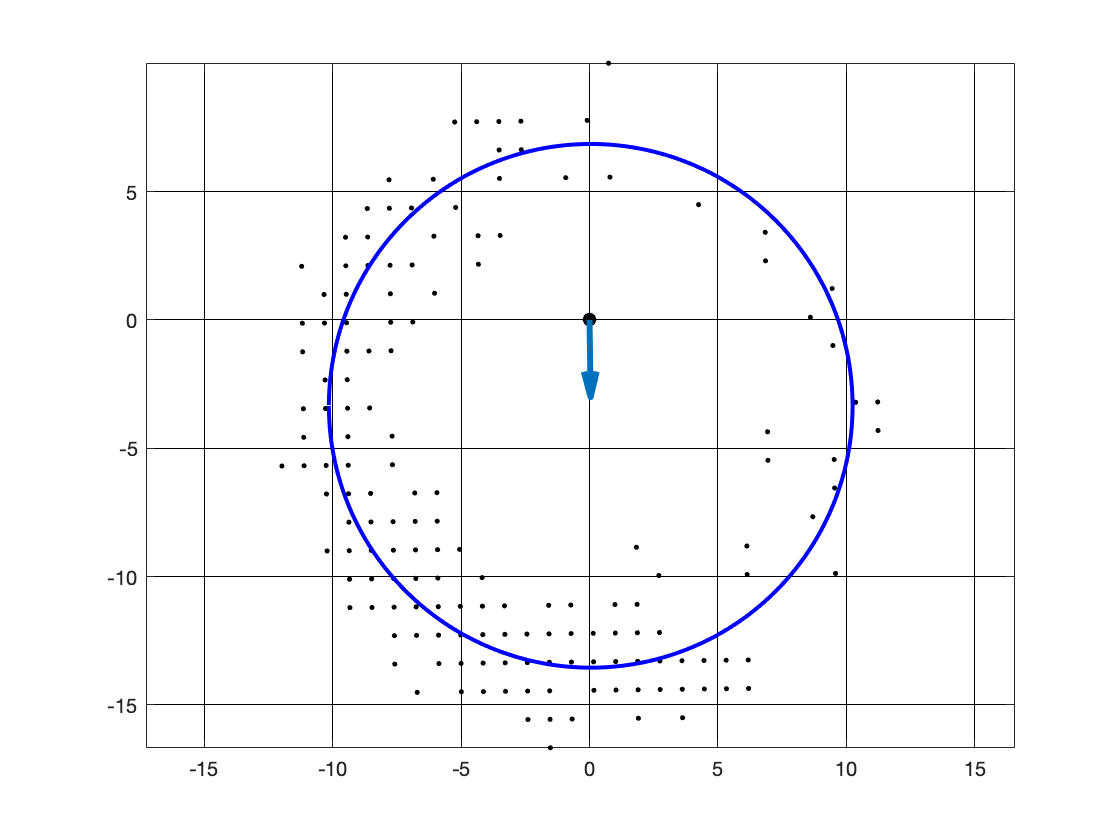

% [xcos,ycos] = vecfit(ccos,x);
[xvec,yvec] = vecfit(cvec,x);

plot(gx,gy,'.k')
hold on
plot(xvec,yvec,'b','LineWidth',2)
% plot(xcos,ycos,'r--','LineWidth',2)
plot(0,0,'ok','MarkerFaceColor','k')
plot(cvec(1)*cos(cvec(2)),cvec(1)*sin(cvec(2)),'k')
quiver(0,0,cvec(1)*cos(cvec(2)),cvec(1)*sin(cvec(2)),'LineWidth',3,'MaxHeadSize',7)
hold off
grid on
ax1 = gca;
ax1.GridColor = [0 0 0];
ax1.GridAlpha = 1;
axis equal

[vw,wd,va,resn,rwh,wInd] = windestimates(spd,dir,ss,se);

% create a colour gradient
len = 2*pi*10000;
red = [1, 0, 0];
blue = [0, 0, 1];
colors_grad = [linspace(red(1), blue(1), len)', linspace(red(2), blue(2), len)', linspace(red(3), blue(3), len)'];
dirCols = -pi:0.0001:pi;
gdCols = find(dirCols > (gd-0.00005) & dirCols < (gd+0.00005));

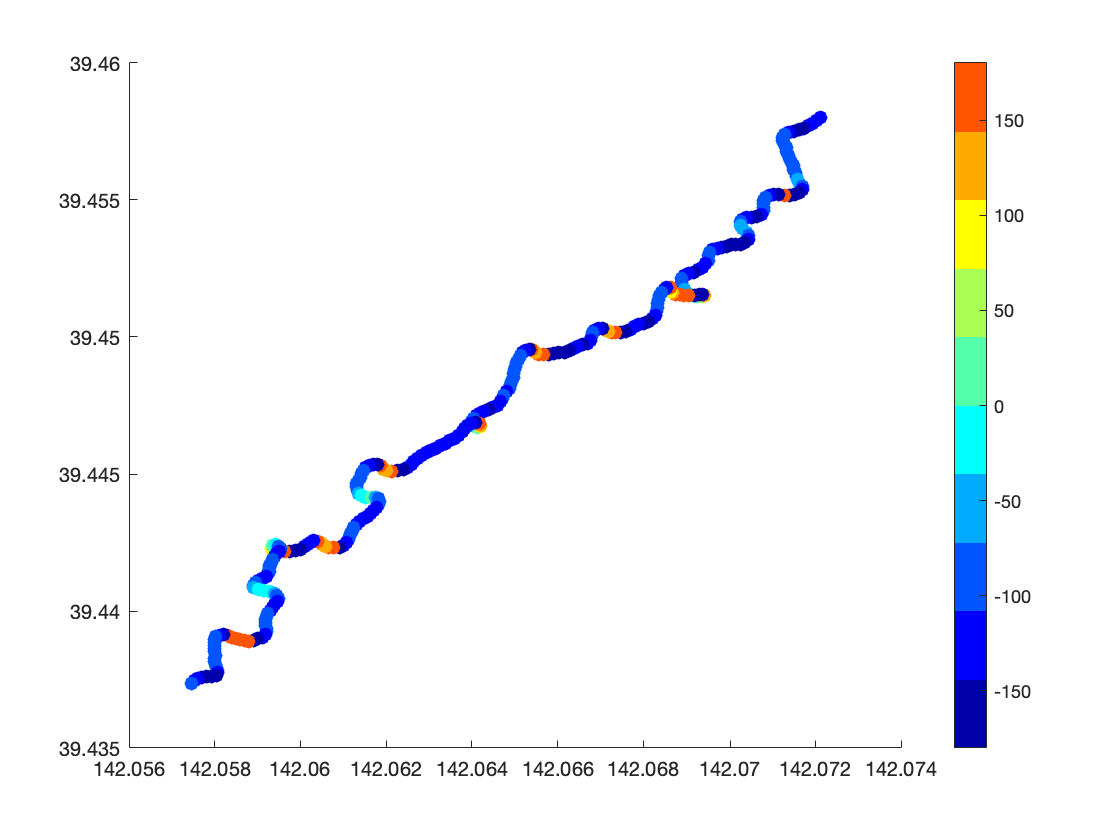

scatter(lon1,lat1,50,gd*(180/pi),"filled")
hcbar = colorbar;
colormap(jet(10));
caxis([-pi*(180/pi) pi*(180/pi)])

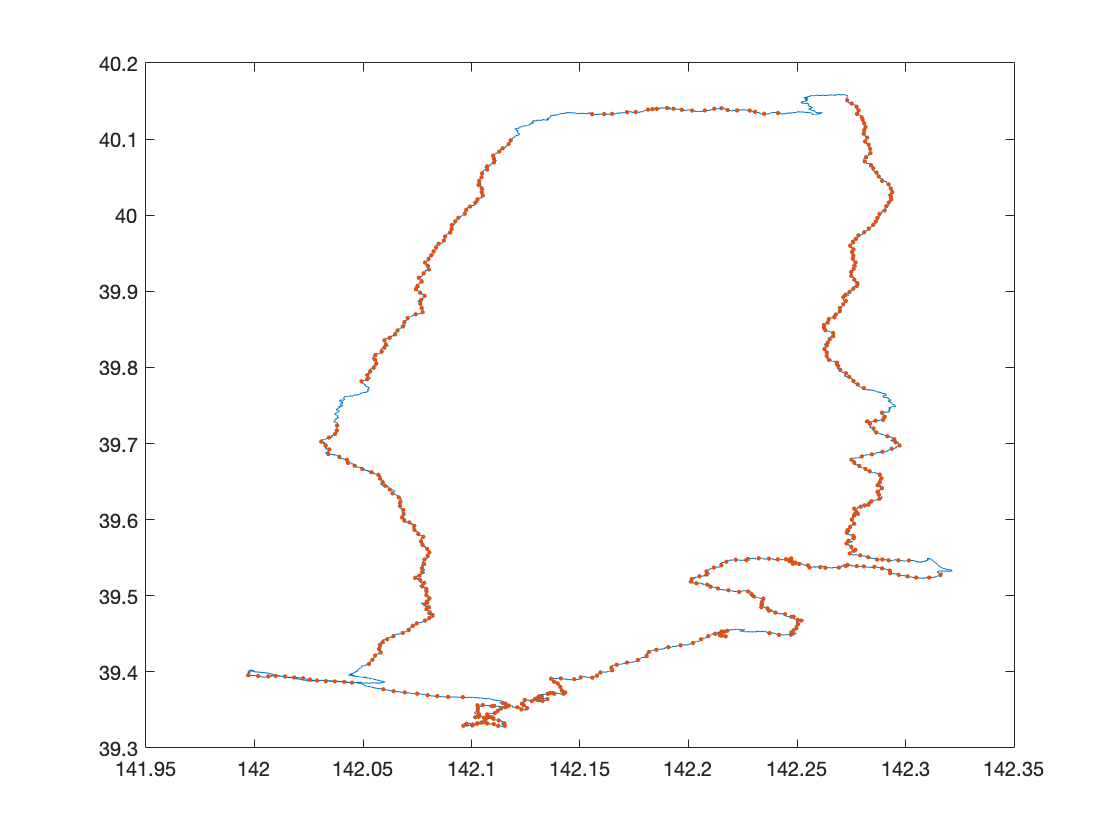

figure
plot(lon,lat)
hold on
plot(lon(wInd(~isnan(wInd))),lat(wInd(~isnan(wInd))),'.','MarkerSize',5)
hold off

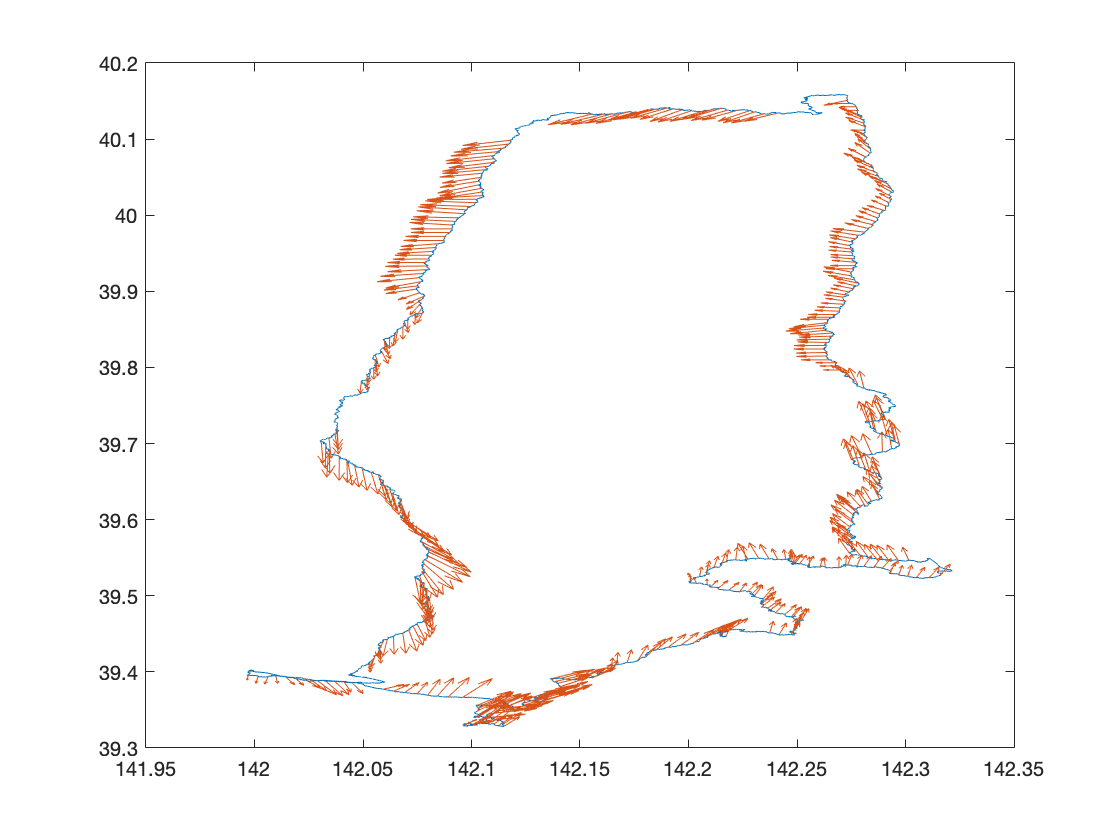

figure
plot(lon,lat)
hold on
u = vw.*cos(wd);
v = vw.*sin(wd);
h = quiver(lon(wInd(~isnan(wInd))),lat(wInd(~isnan(wInd))),u(~isnan(wInd)),v(~isnan(wInd)));
hold off

## Testing the method on 1 fix per 5 seconds data

if ismac()
    fileloc = "/Volumes/GoogleDrive/My Drive/PhD/Data/2019Shearwater/AxyTrek/";
else
    fileloc = "F:/UTokyoDrive/PhD/Data/2019Shearwater/AxyTrek/";
end
files = dir2(strcat(fileloc,"**/*.txt"));
%files = files(3:end);
% extract file names
filesNs = string(split([files.name],'.txt'));
filesNs = filesNs(contains(filesNs,"_S"));
folderNames = ["2018-01" "2018-03" "2018-04" "2018-05" "No.1" "No.2" "No.3" "No.4" "No.5"];
tags = ["2018-01" "2018-03" "2018-04" "2018-05" "1_S1" "2_S1" "3_S1" "4_S1" "5_S1"];

dat = cell(length(tags),5);
for tg = 1:length(tags)
    tagfiles = files(startsWith(filesNs,tags(tg))).name;
    fileID = fopen(strcat(fileloc,folderNames(tg),'/' ,tagfiles));
    GPSDat = textscan(fileID, '%{yyyy/MM/dd,HH:mm:ss}D %f %f %f %f %f %f %f','Delimiter','\t','HeaderLines',1);
    fclose(fileID);
    dat{tg,3} = GPSDat{1};
    dat{tg,4} = GPSDat{2};
    dat{tg,5} = GPSDat{3};
end

[time, lat, lon] = gettimelatlon(dat, 1);
[x,y,zone] = deg2utm(lat,lon); % convert from dec degs to UTM
DistTrav = sqrt(diff(x).^2+diff(y).^2); % calculate distance between GPS points
tdiff = diff(time); % time difference between GPS points
spd = DistTrav./seconds(tdiff); % speed travelled, m^-2
dir = atan2(diff(y),diff(x));
[flight,fs,fe] = flightmask(spd,4,5);
[ss,se] = getsection(5/60,300,60,fs,fe);
[vw,wd,va,resn,rwh,wInd] = windestimates(spd,dir,ss,se);

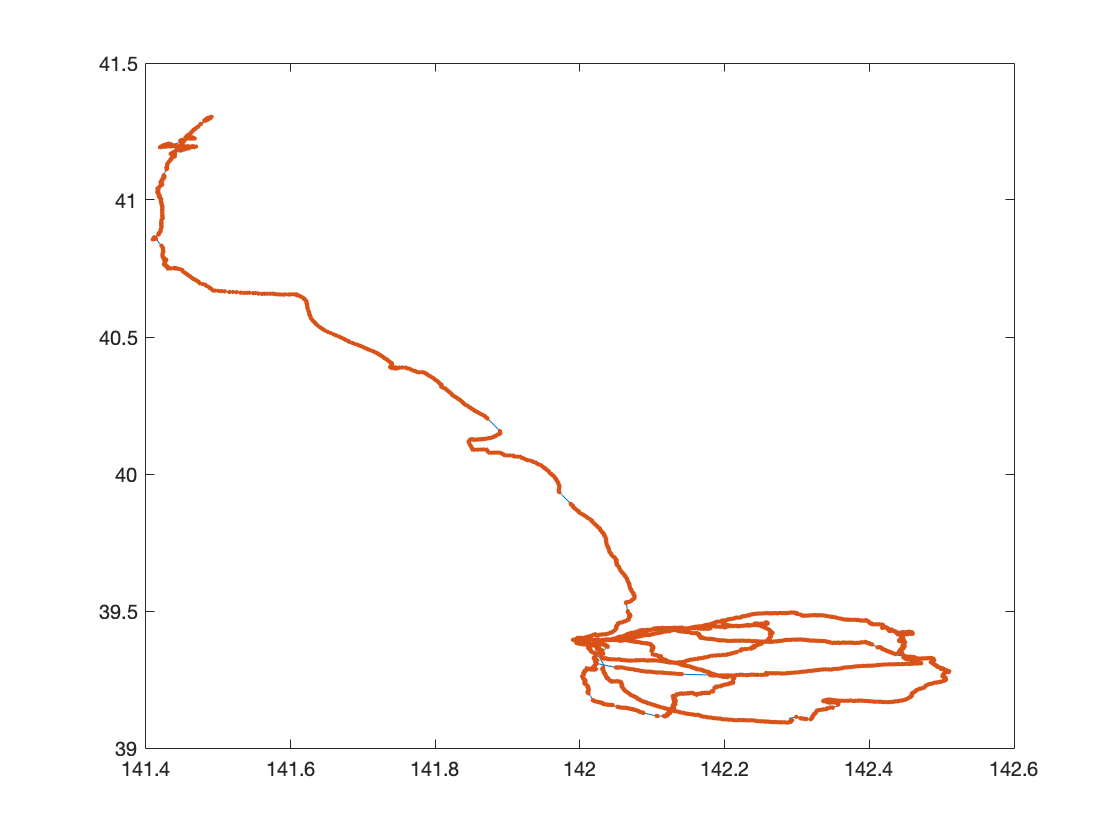

figure
plot(lon,lat)
hold on
plot(lon(wInd(~isnan(wInd))),lat(wInd(~isnan(wInd))),'.','MarkerSize',5)
hold off

## Wind and foraging data

if ismac()
    fileloc = "/Volumes/GoogleDrive/My Drive/PhD/Data/2016Shearwater/TxtDat/BehaviourDetection/PredictedForage/";
else
    fileloc = "F:/UTokyoDrive/PhD/Data/2016Shearwater/TxtDat/BehaviourDetection/PredictedForage/";
end
files = dir2(strcat(fileloc,"*ForageGPS.txt"));
%files = files(3:end);
% extract file names
filesNs = string(split([files.name],'.txt'));
filesNs = filesNs(contains(filesNs,"2016"));
% get file names and dates
tags = strings(length(filesNs),1);
for b = 1:length(filesNs)
    file = char(filesNs(b));
    tags(b) = file(1:strfind(file,'2016')-1);
end
clear file i
% select only unique tag names and find the index of last occurrence
[tags,te] = unique(tags,'last');

dat = cell(length(tags),5);
for tg = 1:length(tags)
    tagfiles = filesNs(startsWith(filesNs,tags(tg)));
    for b = 1:length(tagfiles)
        fileID = fopen(strcat(fileloc,tagfiles(b),".txt"));
        GPSDat = textscan(fileID, '%{dd-MM-yyyy HH:mm:ss}D %f %f %f','Delimiter',',','HeaderLines',1);
        fclose(fileID);
        if b > 1
            dat{tg,3} = vertcat(dat{tg,3},GPSDat{1});
            dat{tg,3} = vertcat(dat{tg,3},GPSDat{1});
            dat{tg,4} = vertcat(dat{tg,4},GPSDat{2});
            dat{tg,5} = vertcat(dat{tg,5},GPSDat{3});
            dat{tg,6} = vertcat(dat{tg,6},GPSDat{4});
        end
        dat{tg,3} = GPSDat{1};
        dat{tg,4} = GPSDat{2};
        dat{tg,5} = GPSDat{3};
        dat{tg,6} = GPSDat{4};
    end
end

% or load in finished data
% if ismac()
%     save('/Volumes/GoogleDrive/My Drive/PhD/Data/2016Shearwater/MatlabDat/ReadIn/AllGPSForage.mat','dat');
% else
%     save('F:/UTokyoDrive/PhD/Data/2016Shearwater/MatlabDat/ReadIn/AllGPSForage.mat','dat');
% end
if ismac()
    load('/Volumes/GoogleDrive/My Drive/PhD/Data/2016Shearwater/MatlabDat/ReadIn/AllGPSForage.mat');
else
    load('F:/UTokyoDrive/PhD/Data/2016Shearwater/MatlabDat/ReadIn/AllGPSForage.mat');
end

## Repeat for 2019 data

if ismac()
    fileloc = "/Volumes/GoogleDrive/My Drive/PhD/Data/2019Shearwater/TxtDat/AxyTrek/BehaviourDetection/PredictedForage/";
else
    fileloc = "F:/UTokyoDrive/PhD/Data/2019Shearwater/TxtDat/AxyTrek/BehaviourDetection/PredictedForage/";
end
files = dir2(strcat(fileloc,"*ForageGPS.txt"));
%files = files(3:end);
% extract file names
filesNs = string(split([files.name],'.txt'));
filesNs = filesNs(contains(filesNs,"2019"));
% get file names and dates
tags = strings(length(filesNs),1);
for b = 1:length(filesNs)
    file = char(filesNs(b));
    tags(b) = file(1:strfind(file,'-2019')-1);
end
clear file i
% select only unique tag names and find the index of last occurrence
[tags,te] = unique(tags,'last');

dat = cell(length(tags),5);
for tg = 1:length(tags)
    tagfiles = filesNs(startsWith(filesNs,tags(tg)));
    for b = 1:length(tagfiles)
        fileID = fopen(strcat(fileloc,tagfiles(b),".txt"));
        GPSDat = textscan(fileID, '%{dd-MM-yyyy HH:mm:ss}D %f %f %f','Delimiter',',','HeaderLines',1);
        fclose(fileID);
        if b > 1
            dat{tg,3} = vertcat(dat{tg,3},GPSDat{1});
            dat{tg,4} = vertcat(dat{tg,4},GPSDat{2});
            dat{tg,5} = vertcat(dat{tg,5},GPSDat{3});
            dat{tg,6} = vertcat(dat{tg,6},GPSDat{4});
        else
            dat{tg,3} = GPSDat{1};
            dat{tg,4} = GPSDat{2};
            dat{tg,5} = GPSDat{3};
            dat{tg,6} = GPSDat{4};
        end
    end
end

% or load in finished data
% if ismac()
%     save('/Volumes/GoogleDrive/My Drive/PhD/Data/2019Shearwater/MatlabDat/AxyTrek/ReadIn/AllGPSForage.mat','dat');
% else
%     save('F:/UTokyoDrive/PhD/Data/2019Shearwater/MatlabDat/AxyTrek/ReadIn/AllGPSForage.mat','dat');
% end
if ismac()
    load('/Volumes/GoogleDrive/My Drive/PhD/Data/2019Shearwater/MatlabDat/AxyTrek/ReadIn/AllGPSForage.mat');
else
    load('F:/UTokyoDrive/PhD/Data/2019Shearwater/MatlabDat/AxyTrek/ReadIn/AllGPSForage.mat');
end

## Trials for window length

The Yonehara-san method extracts data within a 5-minute window which provides ~300 data points when sampled at 1 Hz. The data from 2019 and (some of) 2018 are sampled at 0.2 Hz (1 fix per 5 seconds). This will obviously produce fewer data points if the same window length is used, so first thing to do is check how much variation is caused by changing this window size. 

We can set up 3 trials, the first using a 25 minute window (creating the same number of data points as the original method, a second with a 10 minute window, and finally the same 5 minute window as the original. Comparing the wind speeds and directions produced by the 3 trials should show the impacts of this variation in window length.

windowSize = [300, 600, 1500];
wSpeeds = cell(length(dat), 3);
wDir = cell(length(dat), 3);
wInds = cell(length(dat), 3);

for b = 1:length(dat)
    for trial = 1:3
        [time, lat, lon] = gettimelatlon(dat, b);
        [x,y,zone] = deg2utm(lat,lon); % convert from dec degs to UTM
        DistTrav = sqrt(diff(x).^2+diff(y).^2); % calculate distance between GPS points
        tdiff = diff(time); % time difference between GPS points
        spd = DistTrav./seconds(tdiff); % speed travelled, m^-2
        dir = atan2(diff(y),diff(x));
        [flight,fs,fe] = flightmask(spd,4,5);
        [ss,se] = getsection(.2,windowSize(trial),60,fs,fe);
        [wSpeeds{b,trial},wd{b,trial},va,resn,rwh,wInds{b,trial}] = windestimates(spd,dir,ss,se);
    end
end

Find the overlapping points and compare wind speeds.

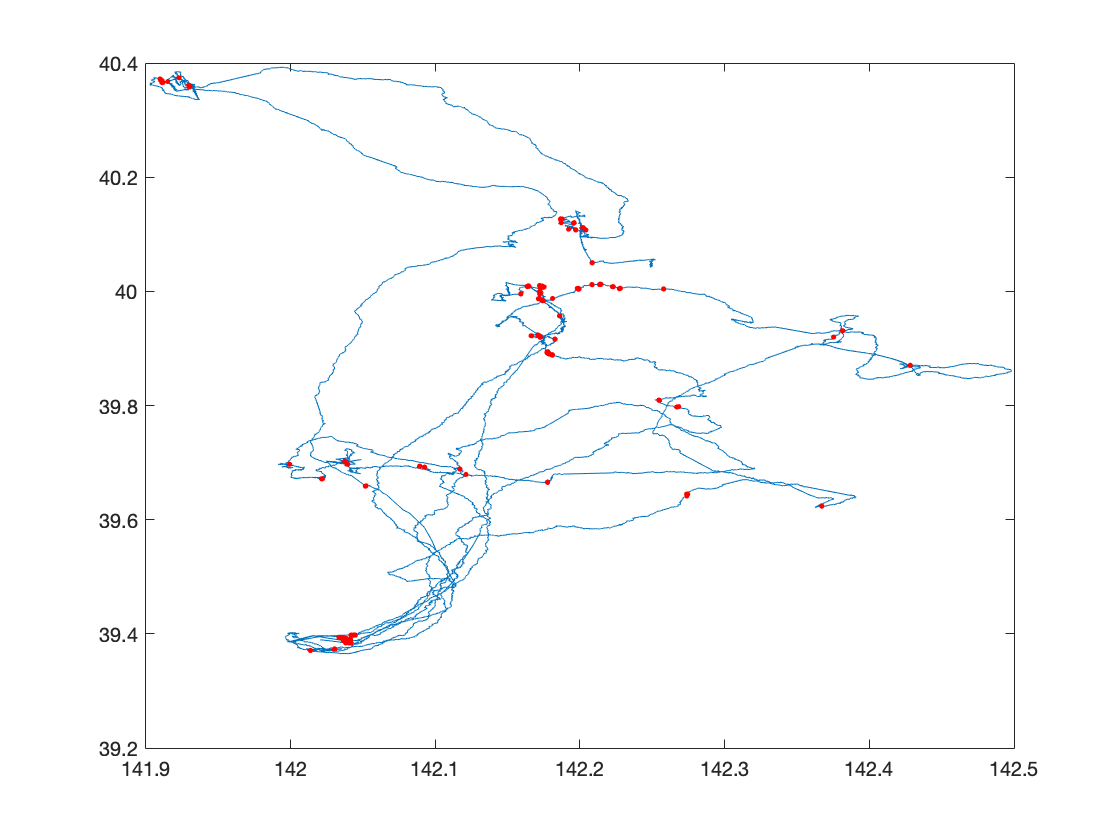

%for tag = 1:length(dat)
%for b = 1:length(lats{tag,3})
figure
plot(lon,lat)
hold on
plot(lon(dat{1,6} == 1),lat(dat{1,6} == 1),'.',"color","red")
hold off

Run the wind analysis for each tag.

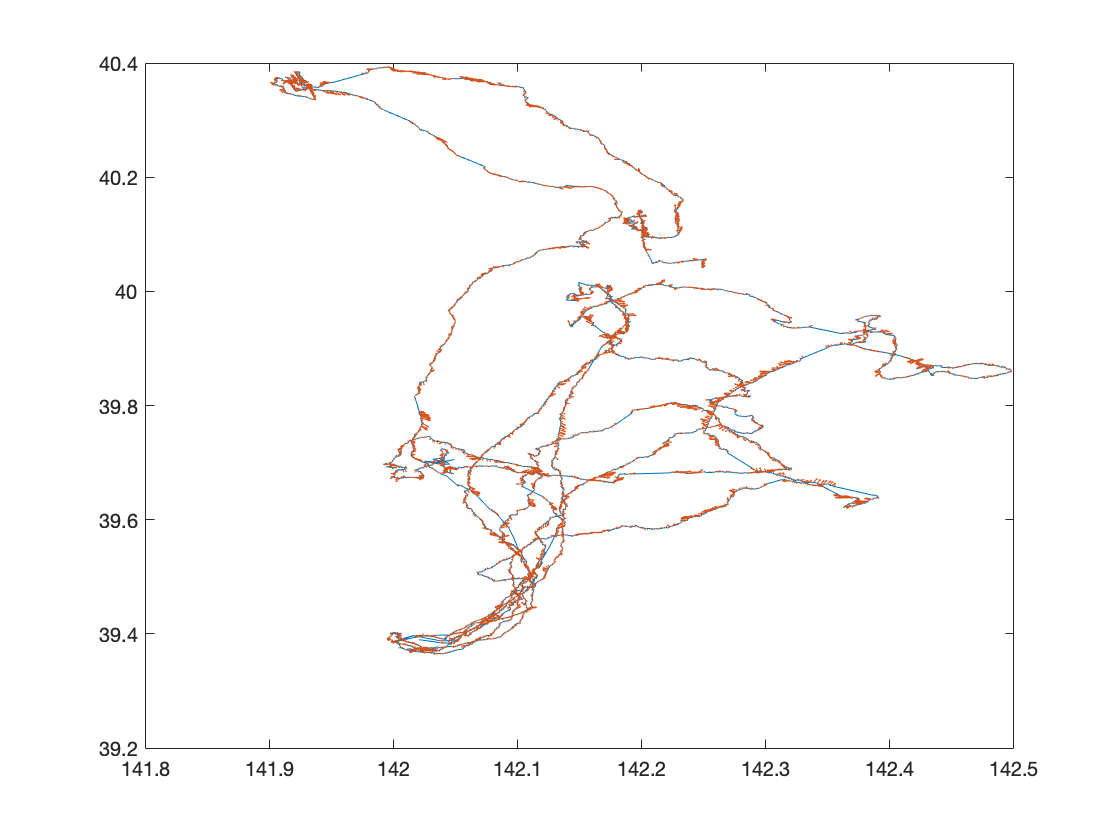

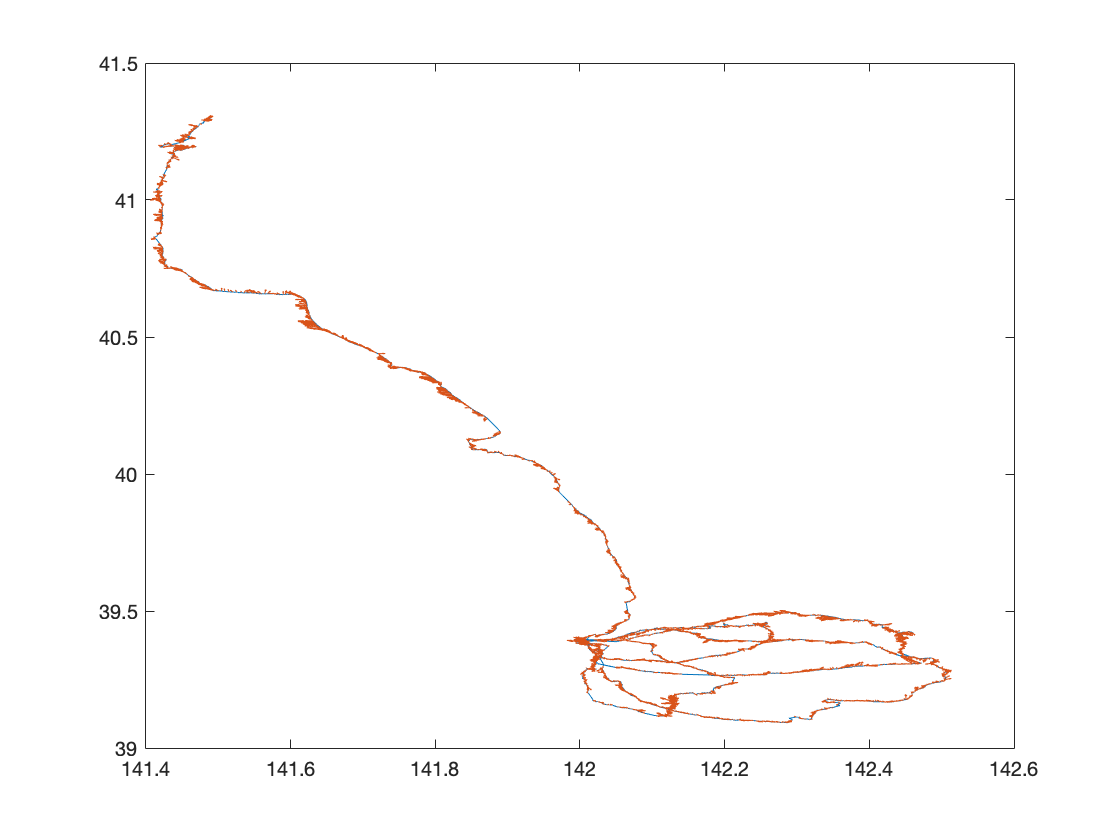

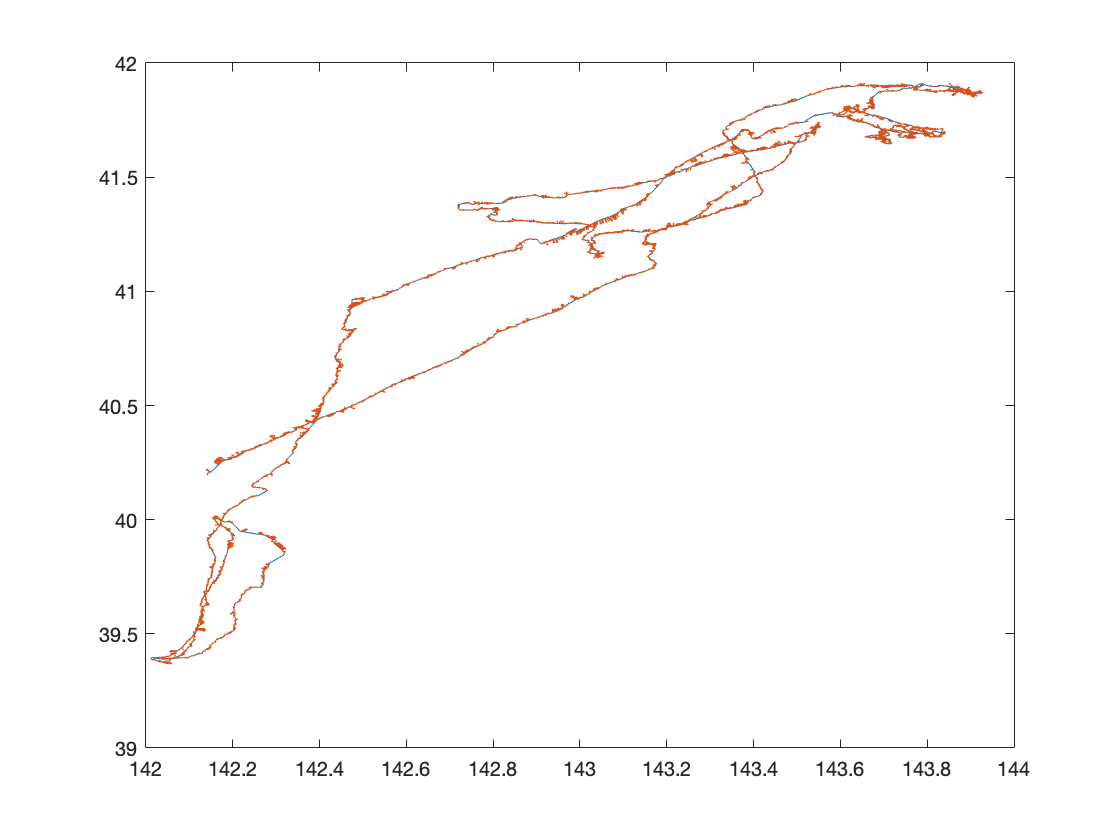

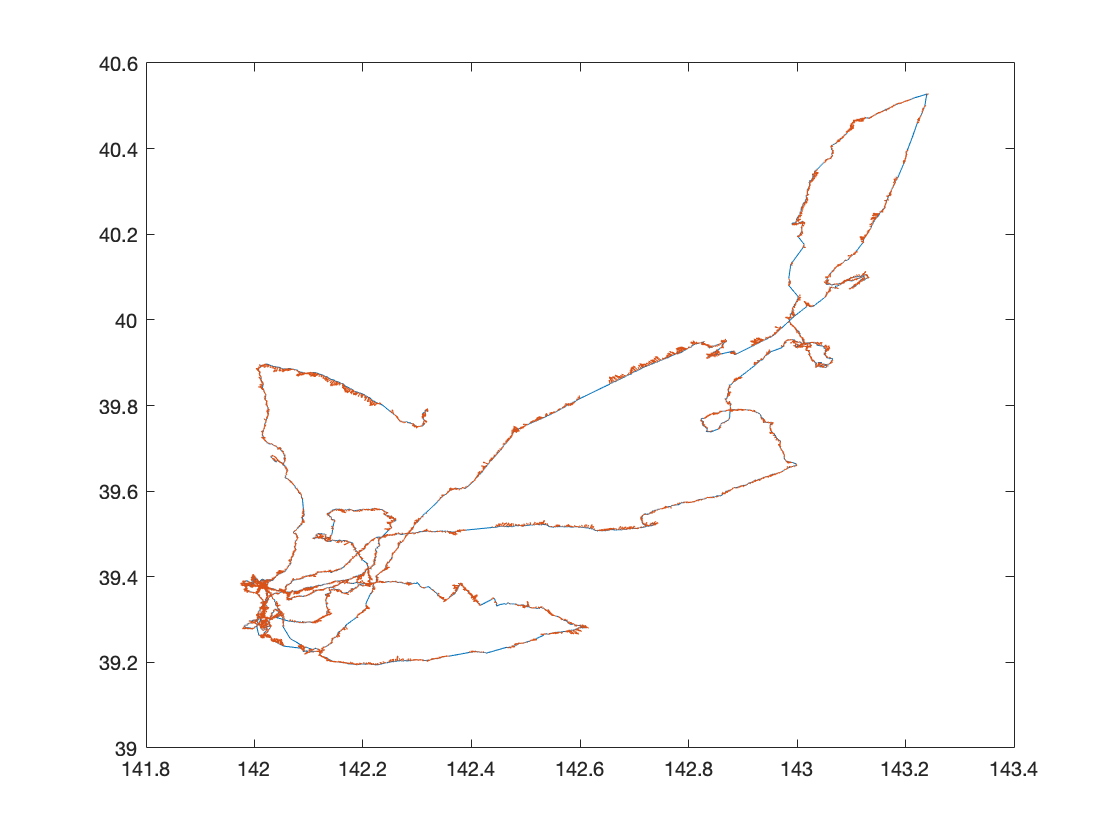

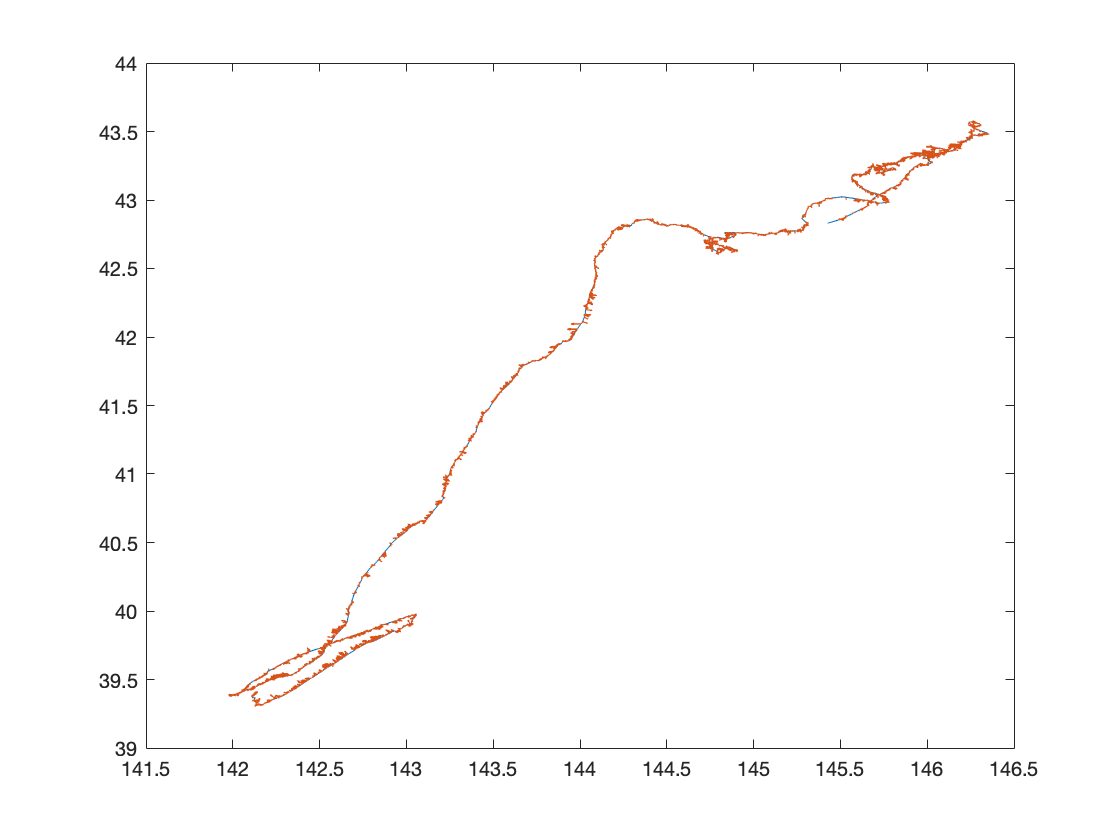

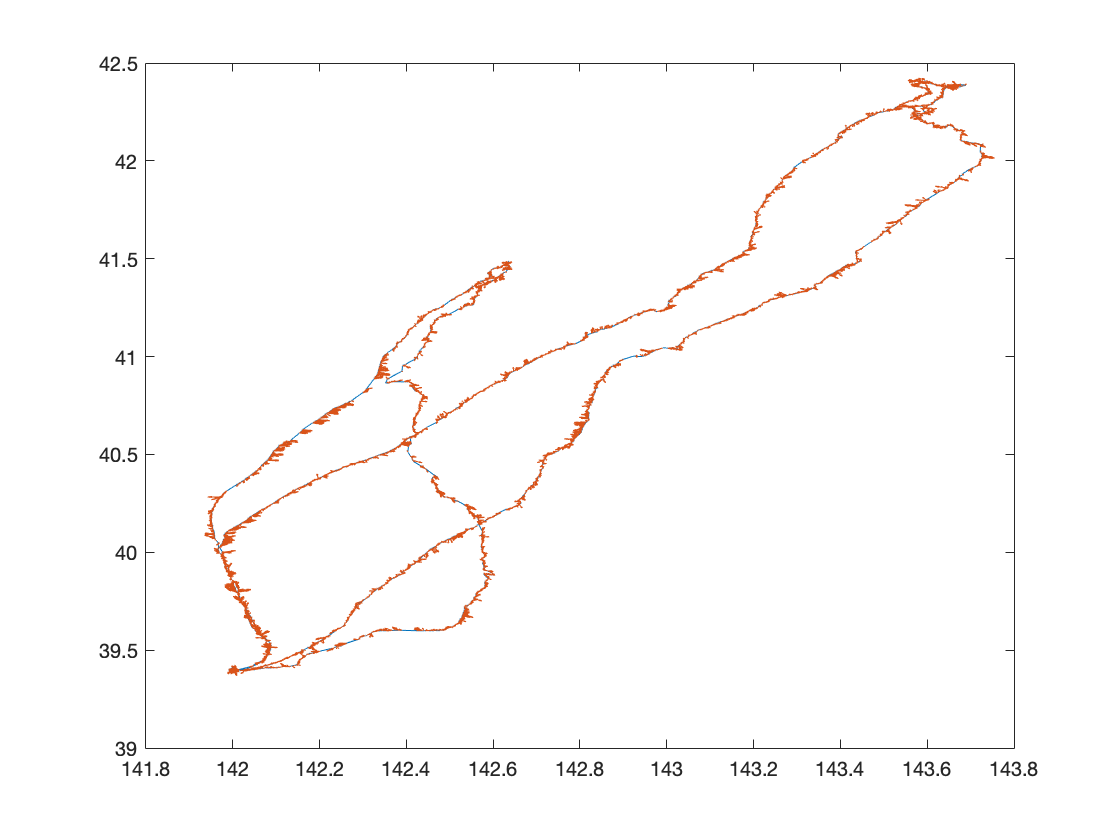

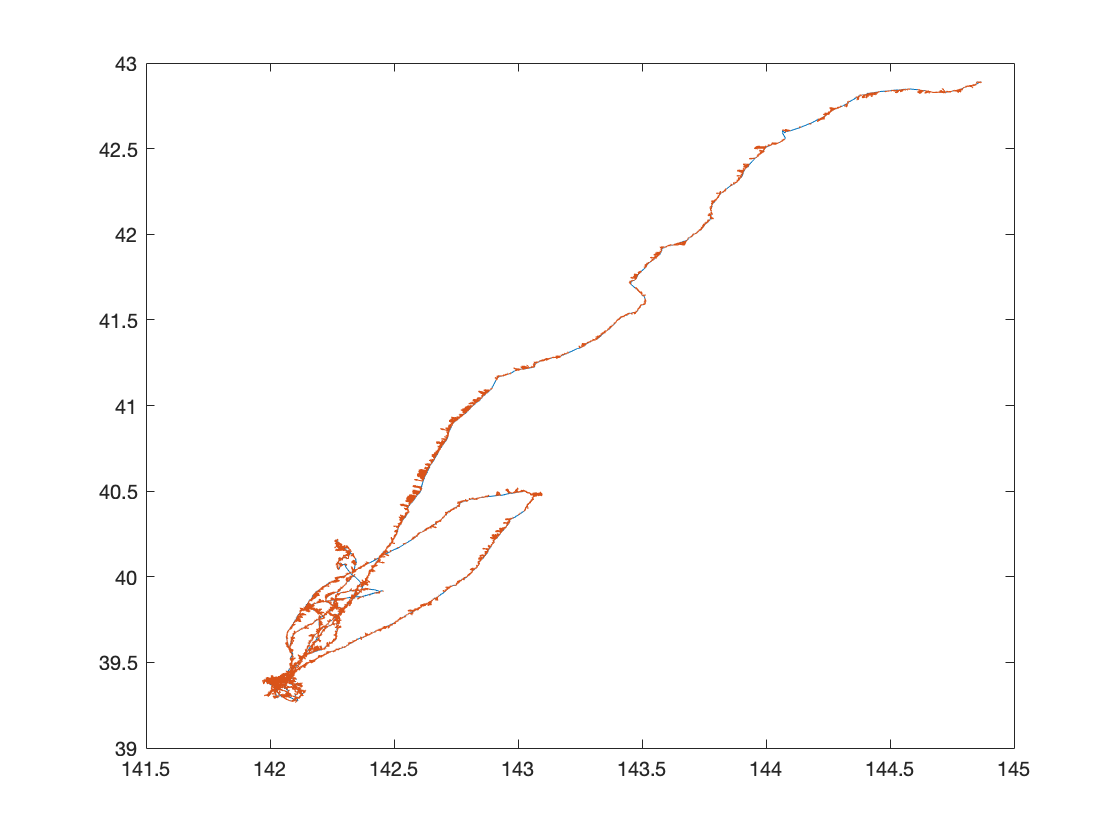

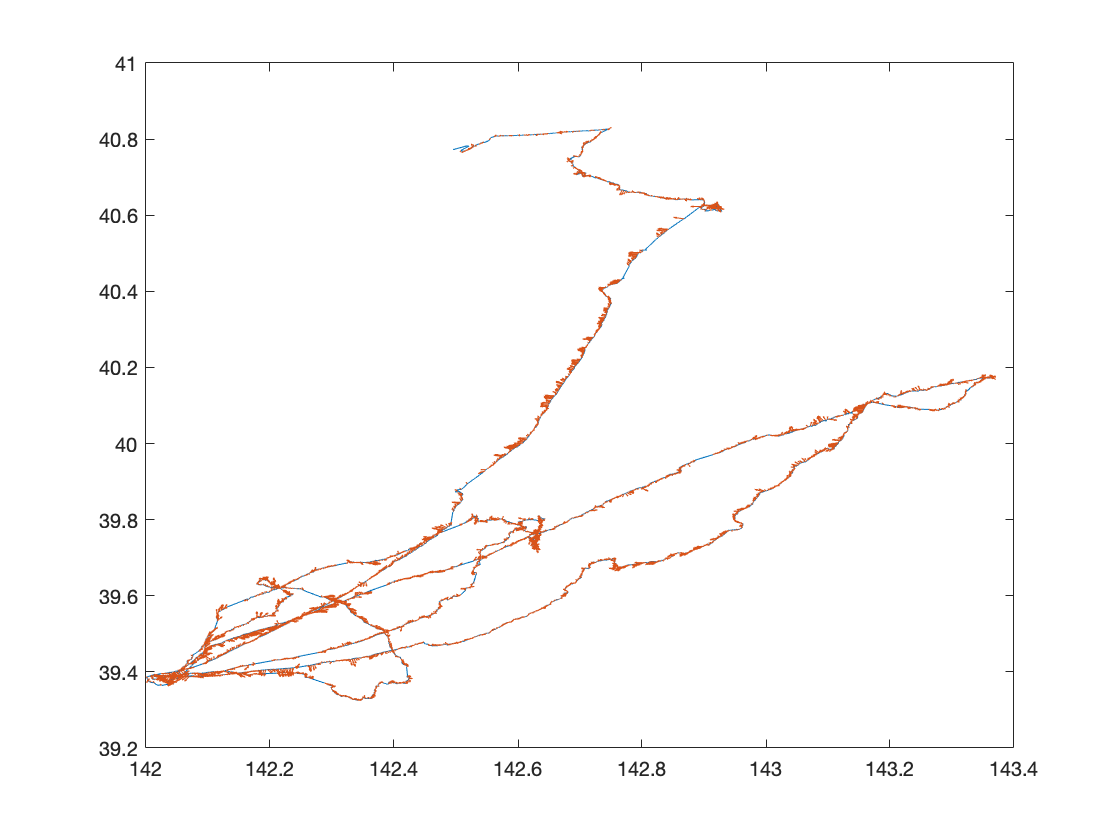

for b = 1:length(dat)
    [time, lat, lon] = gettimelatlon(dat, b);
    [x,y,zone] = deg2utm(lat,lon); % convert from dec degs to UTM
    DistTrav = sqrt(diff(x).^2+diff(y).^2); % calculate distance between GPS points
    tdiff = diff(time); % time difference between GPS points
    spd = DistTrav./seconds(tdiff); % speed travelled, m^-2
    dir = atan2(diff(y),diff(x));
    [flight,fs,fe] = flightmask(spd,4,5);
    [ss,se] = getsection(.2,300,60,fs,fe);
    [vw,wd,va,resn,rwh,wInd] = windestimates(spd,dir,ss,se);
    figure
    plot(lon,lat)
    hold on
    u = vw.*cos(wd);
    v = vw.*sin(wd);
    h = quiver(lon(wInd(~isnan(wInd))),lat(wInd(~isnan(wInd))),u(~isnan(wInd)),v(~isnan(wInd)));
    hold off
end